# Smartfin Filter Analysis

As Smartfin contains an intertial measurement unit (IMU) as well as a magnetometer, we will consider both [ahrsfilter](https://www.mathworks.com/help/fusion/ref/ahrsfilter-system-object.html) and [imufilter](https://www.mathworks.com/help/nav/ref/imufilter-system-object.html).  While ahrsfilter may be more robust since it takes into account additional data, the additional calibration of the magnetometer may reduce the value of this additional information.  Therefore, if possible, we may opt to ignore the magnetometer if there is only minimal accuracy loss.

For this analysis, we will leverage one of the sample datasets provided as part of this repo, which were collected from a VN-300 VectorNav IMU.  This IMU has an internal Kalman filter which can provide roll, pitch, yaw estimates.  As this filter is tuned by the manufacturer, we will use these as a comparison point when testing other Kalman filters.

The dataset we choose to use for this analysis starts with the VN-300 flat on the table.  There is then a brief pitch up to approximately 22 degrees.  Finally, the VN-300 is returned to flat on the table.

data_filename = './sample_data/vectornav_pitch45_5_17.csv';

Below, we load the data from our sample dataset.  To support differing sampling rates, we compute the sampling rate from the dataset.  We then load the data provided by the VN-300.

% Our sample data has headers on the first line, so skip it
data = csvread(data_filename, 1);

% We'll use the time that the sample starts as each time
time = data(:, 1) * 10^(-9);
time = time - time(1);

% Using the first timestamp, calculate the sampling rate.
% With the configuration for the VectorNav, this will remain consistent.
sampling_rate = 1 / (time(2) - time(1));

yaw_pitch_roll_device = data(:, 4:6);
orientation_device = quaternion(angle2quat(yaw_pitch_roll_device(:, 1), yaw_pitch_roll_device(:, 2), yaw_pitch_roll_device(:, 3)));
accel = data(:, 10:12);
gyro = data(:, 7:9);
mag = data(:, 19:21);

Matlab provides tools for tuning the parameters of both filters.  In order to determine if tuning is necessary for realistic results, we will compare untuned and tuned versions of the filter.

ahrs_sensor_data = table;
ahrs_sensor_data.Accelerometer = accel;
ahrs_sensor_data.Gyroscope = gyro;
ahrs_sensor_data.Magnetometer = mag;

imu_sensor_data = table;
imu_sensor_data.Accelerometer = accel;
imu_sensor_data.Gyroscope = gyro;

ground_truth = table;
ground_truth.Orientation = orientation_device;

ahrs_fuse = ahrsfilter('SampleRate', sampling_rate, 'ReferenceFrame', 'ENU');
imu_fuse = imufilter('SampleRate', sampling_rate, 'ReferenceFrame', 'ENU');

orientation_ahrs_untuned = ahrs_fuse(accel, gyro, mag);
orientation_imu_untuned = imu_fuse(accel, gyro);
yaw_pitch_roll_ahrs_untuned = eulerd(orientation_ahrs_untuned,'ZYX','frame');
yaw_pitch_roll_imu_untuned = eulerd(orientation_imu_untuned,'ZYX','frame');

ahrs_cfg = tunerconfig('ahrsfilter');
imu_cfg = tunerconfig('imufilter');
tune(ahrs_fuse, ahrs_sensor_data, ground_truth, ahrs_cfg);
tune(imu_fuse, imu_sensor_data, ground_truth, imu_cfg);

orientation_ahrs_tuned = ahrs_fuse(accel, gyro, mag);
orientation_imu_tuned = imu_fuse(accel, gyro);
yaw_pitch_roll_ahrs_tuned = eulerd(orientation_ahrs_tuned,'ZYX','frame');
yaw_pitch_roll_imu_tuned = eulerd(orientation_imu_tuned,'ZYX','frame');

    Iteration    Parameter                         Metric
    _________    _________                         ______
    1            AccelerometerNoise                2.9254
    1            GyroscopeNoise                    2.9254
    1            MagnetometerNoise                 2.9254
    1            GyroscopeDriftNoise               2.9254
    1            LinearAccelerationNoise           2.9253
    1            MagneticDisturbanceNoise          2.9253
    1            LinearAccelerationDecayFactor     2.9253
    1            MagneticDisturbanceDecayFactor    2.9253
    2            AccelerometerNoise                2.9253
    2            GyroscopeNoise                    2.9253
    2            MagnetometerNoise                 2.9253
    2            GyroscopeDriftNoise               2.9253
    2            LinearAccelerationNoise           2.9253
    2            MagneticDisturbanceNoise          2.9253
    2            LinearAccelerationDec

    Iteration    Parameter                        Metric
    _________    _________                        ______
    1            AccelerometerNoise               2.7402
    1            GyroscopeNoise                   2.7402
    1            GyroscopeDriftNoise              2.7402
    1            LinearAccelerationNoise          2.7402
    1            LinearAccelerationDecayFactor    2.7402
    2            AccelerometerNoise               2.7402
    2            GyroscopeNoise                   2.7402
    2            GyroscopeDriftNoise              2.7402
    2            LinearAccelerationNoise          2.7402
    2            LinearAccelerationDecayFactor    2.7402
    3            AccelerometerNoise               2.7402
    3            GyroscopeNoise                   2.7402
    3            GyroscopeDriftNoise              2.7402
    3            LinearAccelerationNoise          2.7402
    3            LinearAccelerationDecayFactor    2.74

When comparing the calculated yaw, we can see some discrepancies, namely, each filter is biased to a different start location.  For the purposes of estimating wave height, yaw is irrelevant as it does not impact the wave height.  As such, we will simply assume this data is biased at 0.

For pitch and roll, all of the filters are in high agreement, including their tuned and untuned variants. Some of the untuned filters take more time to converge than their tuned counterparts.  As this will be an overall small portion of the surf session, we propose that this can be ignored.

In general, the untuned filter only introduce less than 1% error when compared to their tuned counterparts.  As such, we can subsitute the untuned variant of filters for the tuned variant.  This once again reduces the amount of initial calibration that will need to be done.

Likewise, we find that within these short timeframes, the imufilter and the ahrsfilter are comparable.  As it is possible this observation may not hold on larger datasets, we will continue to evaluate both the imufilter and the ahrsfilter.

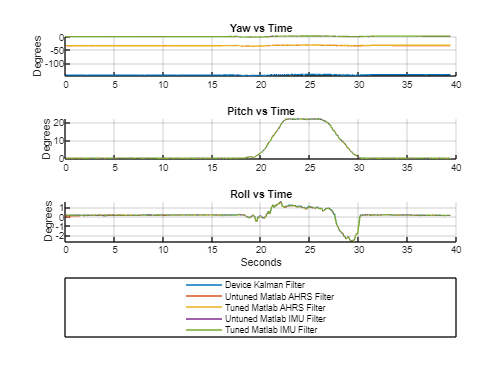

clf;

subplot(4,1,1);
hold on;
h1 = plot(time, yaw_pitch_roll_device(:, 1));
h2 = plot(time, yaw_pitch_roll_ahrs_untuned(:, 1));
h3 = plot(time, yaw_pitch_roll_ahrs_tuned(:, 1));
h4 = plot(time, yaw_pitch_roll_imu_untuned(:, 1));
h5 = plot(time, yaw_pitch_roll_imu_tuned(:, 1));
ylabel("Degrees");
%xlabel("Seconds")
title("Yaw vs Time");
hold off;
grid on;

subplot(4,1,2);
hold on;
plot(time, yaw_pitch_roll_device(:, 2));
plot(time, yaw_pitch_roll_ahrs_untuned(:, 2));
plot(time, yaw_pitch_roll_ahrs_tuned(:, 2));
plot(time, yaw_pitch_roll_imu_untuned(:, 2));
plot(time, yaw_pitch_roll_imu_tuned(:, 2));
ylabel("Degrees");
%xlabel("Seconds");
title("Pitch vs Time");
hold off;
grid on;

subplot(4,1,3);
hold on;
plot(time, yaw_pitch_roll_device(:, 3));
plot(time, yaw_pitch_roll_ahrs_untuned(:, 3));
plot(time, yaw_pitch_roll_ahrs_tuned(:, 3));
plot(time, yaw_pitch_roll_imu_untuned(:, 3));
plot(time, yaw_pitch_roll_imu_tuned(:, 3));
ylabel("Degrees");
xlabel("Seconds")
title("Roll vs Time");
hold off;
grid on;

hLegend = subplot(4,1,4);
posLegend = get(hLegend,'Position');
leg = legend(hLegend,[h1;h2;h3;h4;h5],"Device Kalman Filter", "Untuned Matlab AHRS Filter", "Tuned Matlab AHRS Filter", "Untuned Matlab IMU Filter", "Tuned Matlab IMU Filter");
axis(hLegend,'off');
set(leg,'Position',posLegend);